clc, clear;

% 1. 读取Excel文件的5个sheet
file_path = '亚运会奖牌数据.xlsx';
% 获取Excel文件信息
[~, sheetNames] = xlsfinfo(file_path);


% sheets = [6, 5, 4, 3, 2]; % 使用工作表的索引
sheets = 20:-1:3;

% 初始化结果矩阵
result_matrix = zeros(length(sheets), 45);

% 参加亚运会的队伍列表
% countries = {'阿富汗', '巴林', '孟加拉国', '不丹', '文莱', '柬埔寨', '中国', '中国香港', '中国澳门', ...
%               '印度', '印度尼西亚', '伊朗', '伊拉克', '日本', '约旦', '哈萨克斯坦', '朝鲜', '韩国', '科威特', ...
%               '吉尔吉斯斯坦', '老挝', '黎巴嫩', '马来西亚', '马尔代夫', '蒙古', '缅甸', '尼泊尔', '阿曼', ...
%               '巴基斯坦', '巴勒斯坦', '菲律宾', '卡塔尔', '沙特阿拉伯', '新加坡', '斯里兰卡', '叙利亚', '中国台北', ...
%               '塔吉克斯坦', '泰国', '东帝汶', '土库曼斯坦', '阿拉伯联合酋长国', '乌兹别克斯坦', '越南', '也门'};

countries = {'Afghanistan', 'Bahrain', 'Bangladesh', 'Bhutan', 'Brunei', 'Cambodia', 'China', 'Hong Kong', 'Macau', ...
              'India', 'Indonesia', 'Iran', 'Iraq', 'Japan', 'Jordan', 'Kazakhstan', 'North Korea', 'South Korea', 'Kuwait', ...
              'Kyrgyzstan', 'Laos', 'Lebanon', 'Malaysia', 'Maldives', 'Mongolia', 'Myanmar', 'Nepal', 'Oman', ...
              'Pakistan', 'Palestine', 'Philippines', 'Qatar', 'Saudi Arabia', 'Singapore', 'Sri Lanka', 'Syria', 'Chinese Taipei', ...
              'Tajikistan', 'Thailand', 'Timor-Leste', 'Turkmenistan', 'United Arab Emirates', 'Uzbekistan', 'Vietnam', 'Yemen'};


% 遍历每个sheet
for sheet_index = 1:length(sheets)
    sheet_index_numeric = sheets(sheet_index); % 获取工作表索引
    sheet_name = sheetNames{sheet_index_numeric}; % 直接使用索引作为工作表名称
    
    % 读取B列和F列的数据
    country_data = readcell(file_path, 'Sheet', sheet_name, 'Range', 'B:B');
    medal_data = readmatrix(file_path, 'Sheet', sheet_name, 'Range', 'F:F');
    
    % 初始化当前届的结果向量
    current_sheet_result = zeros(1, 45);
    
    % 遍历每行数据
    for row = 2:length(country_data)
        % 从B列数据中提取国家名称
        full_country_name = string(country_data{row});
        country = extractBetween(full_country_name, 1, strlength(full_country_name));
        
        % 检查是否是需要的国家
        country_index = find(strcmp(countries, country));
        
        if ~isempty(country_index)
            % 更新当前届的结果向量
            current_sheet_result(country_index) = medal_data(row-1);
        end
    end
    
    % 将当前届结果放入总结果矩阵
    result_matrix(sheet_index, :) = current_sheet_result;
end

% 打印结果矩阵
disp('历届亚运会获奖数矩阵：');

历届亚运会获奖数矩阵：



disp(result_matrix);

  列 1 至 24

     0     0     0     0     0     0     0     0     0    34     5     2     0    48     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0    14     0     0     0    43     0     0     0     5     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     9     1     4     0    36     0     0     0     5     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0    14     8     0     0    46     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0    11     1     4     0    50     0     0     0     4     0     0     0     0    12     0
     0     0     0     0     0     0     0     0     0    14     2     3     0    42     0     0     0     7     0     0     0     0     2     0
     0     0     0     0     0     0    21     0     0    15     0     8     2    32     0     0     1     2     1    

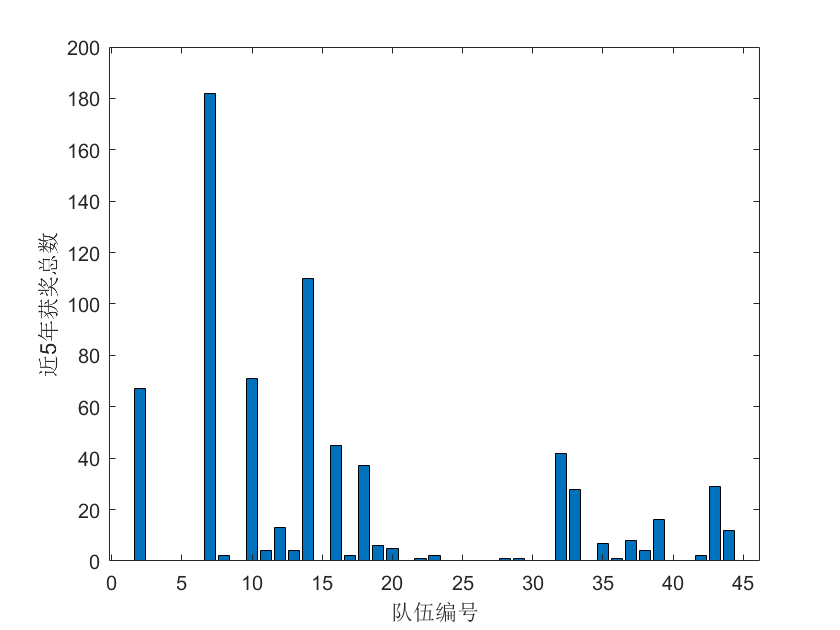

% 统计近5届各个队伍获得奖牌总数
latest_5 = sum(result_matrix(14:1:18,1:end),1);

% 以获奖数对这45个队伍进行分组，分为：A组（<=10），B组(<=50)，C组(>50)（用1，2，3编号）
% 获得每个国家编号对应的组号
latest_5_class = zeros(1,45);
for i=1:45
    if latest_5(1,i)>10*5
       latest_5_class(1,i) = 3;
       
    elseif latest_5(1,i)>10
        latest_5_class(1,i) = 2;
    else
        latest_5_class(1,i) = 1;
    end
end
min_flags = latest_5_class*5+5; 
min_total = sum(min_flags);

% 绘制近5届奖牌数，分组情况以及每个队伍准备的最少旗帜数
figure;
bar(latest_5)
xlabel('队伍编号');
ylabel('近5年获奖总数');

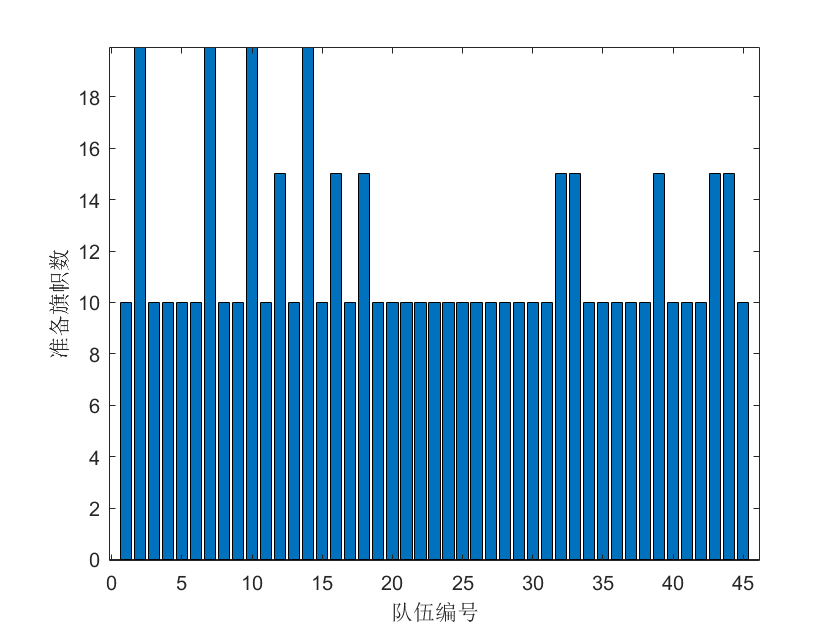


figure;
bar(min_flags)
xlabel('队伍编号');
ylabel('准备旗帜数');


% result_matrix是一个5x45的矩阵，countries是一个包含国家名称的cell数组

% 初始化新矩阵
new_matrix = cell(19, 46);

% 将国家名称添加到首行
new_matrix(1, 2:end) = countries;

% 将年份添加到首列
new_matrix(2:end, 1) = {'1951','1954','1958','1962','1966','1970','1974','1978','1982','1986','1990','1994','1998','2002', '2006', '2010', '2014', '2018'};

% 将result_matrix的数据复制到新矩阵中
for i = 1:18
    new_matrix(i+1, 2:end) = num2cell(result_matrix(i, :));
end

% 打印新矩阵
disp(new_matrix);

  列 1 至 9

    {0×0 double}    {'Afghanistan'}    {'Bahrain'}    {'Bangladesh'}    {'Bhutan'}    {'Brunei'}    {'Cambodia'}    {'China'}    {'Hong Kong'}
    {'1951'    }    {[          0]}    {[      0]}    {[         0]}    {[     0]}    {[     0]}    {[       0]}    {[    0]}    {[        0]}
    {'1954'    }    {[          0]}    {[      0]}    {[         0]}    {[     0]}    {[     0]}    {[       0]}    {[    0]}    {[        1]}
    {'1958'    }    {[          0]}    {[      0]}    {[         0]}    {[     0]}    {[     0]}    {[       0]}    {[    0]}    {[        0]}
    {'1962'    }    {[          0]}    {[      0]}    {[         0]}    {[     0]}    {[     0]}    {[       0]}    {[    0]}    {[        0]}
    {'1966'    }    {[          0]}    {[      0]}    {[         0]}    {[     0]}    {[     0]}    {[       0]}    {[    0]}    {[        0]}
    {'1970'    }    {[          0]}    {[      0]}    {[         0]}    {[     0]}    {[     0]}    {[       0]}    {[    0]}    {[


% 归一化处理
for i = 2:19
    % 计算每行的和
    row_sum = sum(cell2mat(new_matrix(i, 2:end)));
    
    % 对每个元素进行归一化处理
    new_matrix(i, 2:end) = num2cell(cell2mat(new_matrix(i, 2:end)) / row_sum);
end

% 打印归一化后的矩阵
disp(new_matrix);

  列 1 至 9

    {0×0 double}    {'Afghanistan'}    {'Bahrain'}    {'Bangladesh'}    {'Bhutan'}    {'Brunei'}    {'Cambodia'}    {'China' }    {'Hong Kong'}
    {'1951'    }    {[          0]}    {[      0]}    {[         0]}    {[     0]}    {[     0]}    {[       0]}    {[     0]}    {[        0]}
    {'1954'    }    {[          0]}    {[      0]}    {[         0]}    {[     0]}    {[     0]}    {[       0]}    {[     0]}    {[   0.0122]}
    {'1958'    }    {[          0]}    {[      0]}    {[         0]}    {[     0]}    {[     0]}    {[       0]}    {[     0]}    {[        0]}
    {'1962'    }    {[          0]}    {[      0]}    {[         0]}    {[     0]}    {[     0]}    {[       0]}    {[     0]}    {[        0]}
    {'1966'    }    {[          0]}    {[      0]}    {[         0]}    {[     0]}    {[     0]}    {[       0]}    {[     0]}    {[        0]}
    {'1970'    }    {[          0]}    {[      0]}    {[         0]}    {[     0]}    {[     0]}    {[       0]}    {[     0]


% 指定要保存到的 Excel 文件路径
file_path = 'output.xlsx';

% 使用 writematrix 将矩阵保存到 Excel 文件
writecell(new_matrix, file_path);




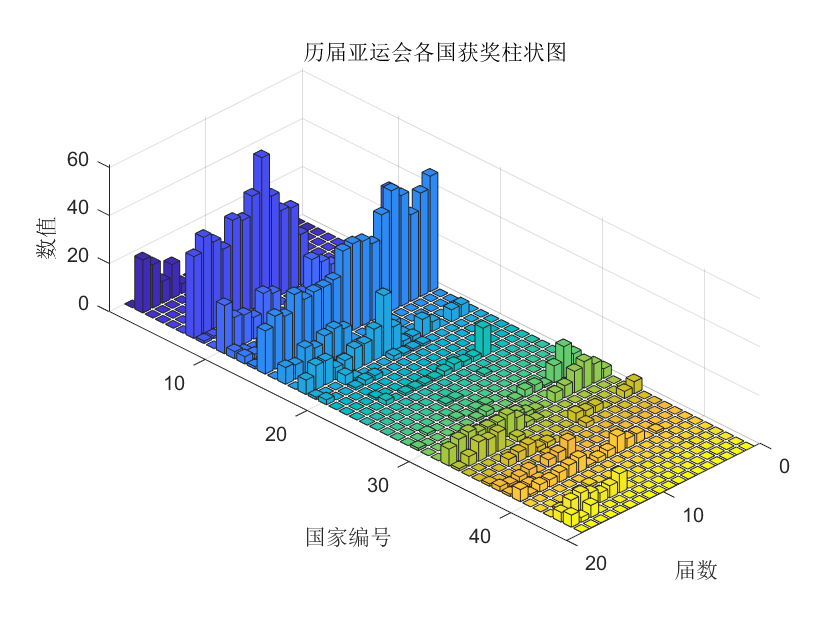

%% 绘制历届亚运会各国获奖柱状图
% 获取矩阵的行和列数
[num_rows, num_columns] = size(result_matrix);

% 创建行和列的坐标
x = 1:num_columns;
y = 1:num_rows;

% 生成网格坐标
[X, Y] = meshgrid(x, y);

% 使用 bar3 函数绘制三维柱状图
figure;
bar3(result_matrix);

% 添加轴标签和标题
xlabel('国家编号');
ylabel('届数');
zlabel('数值');
title('历届亚运会各国获奖柱状图');

% 设置图形属性
grid on;
colormap('parula');  % 设置颜色映射

% 调整视角
view(45, 30);

## 绘制预测的2023（19届）以及历届亚运会各国获奖占比柱状图

%% 绘制预测的2023（19届）以及历届亚运会各国获奖占比柱状图
% 获取矩阵的行和列数
res = Z(1:19,2:46);

函数或变量 'Z' 无法识别。

[num_rows, num_columns] = size(res);

% 创建行和列的坐标
x = 1:num_columns;
y = 1:num_rows;

% 生成网格坐标
[X, Y] = meshgrid(x, y);

% 使用 bar3 函数绘制三维柱状图
figure;
bar3(res);

% 添加轴标签和标题
xlabel('国家编号');
ylabel('届数');
zlabel('数值');
title('历届亚运会各国获奖占比柱状图');

% 设置图形属性
grid on;
colormap('parula');  % 设置颜色映射

% 调整视角
view(45, 30);

## 绘制各队伍最佳旗帜准备数量柱状图

%% 绘制各队伍最佳旗帜准备数量柱状图
predict = xlsread('predict.xlsx', 'Sheet1');
best_flag = predict(22,2:46);
bar(best_flag)
xlabel('队伍编号');
ylabel('最佳准备旗帜数');


